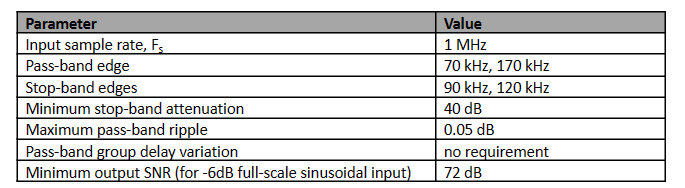

%Requirements
fs = 1e6;
fp1 = 70e3;
fp2 = 170e3;
fs1 = 90e3;
fs2 = 120e3;
Atten = 40;
PBRipple = 0.05;
SNR = 72;

wp1 = 2*fp1/fs;
wp1 = wp1 * pi;

wp2 = 2*fp2/fs;
wp2 = wp2 * pi;

ws1 = 2*fs1/fs;
ws1 = ws1 * pi;

ws2 = 2*fs2/fs;
ws2 = ws2 * pi;

%Values
bits = 13

bits = 13

order = 6

order = 6

wc = 0.1 *pi; %arbitrary
lambda=(cos((wp2+wp1)/2))/(cos((wp2-wp1)/2));

%% BandStop
p = tan((wp2-wp1)/2)*tan(wc/2);
ws1_hat = abs(2*atan(p*sin(ws1)/(cos(ws1)-lambda)))/pi;
ws1_hat = ws1_hat *pi;
ws2_hat = abs(2*atan(p*sin(ws2)/(cos(ws2)-lambda)))/pi;
ws2_hat = ws2_hat *pi;

%% chose more stringent stopband freq
if ws1<ws2
    ws_hat = ws1_hat;
else
    ws_hat = ws2_hat;
end

wp_hat = wc;

%%prewarp
omega_p = tan(wp_hat/2);
omega_s = tan(ws_hat/2);

%finding order
syms x
eqn = 20*log10(sqrt(1+x^2)) == PBRipple;
epsilon = double(solve(eqn));
epsilon = epsilon(1);
eqn = 20*log10(x) == Atten;
A = double(solve(eqn));

k = omega_p/omega_s;
k1 = epsilon/(sqrt(A^2-1));
k1 = k1(1);
min_order = acosh(1/k1)/acosh(1/k); 
min_order = ceil(min_order); %minimum order number to meet Passband Ripple and Attenuation
max_order = 2*epsilon *2^bits;
max_order = floor(max_order); %max order to meet bit length given passpand ripple

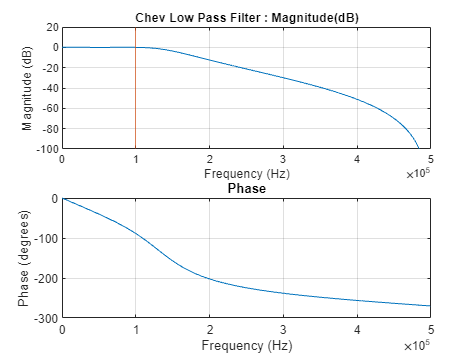

fc = 100e3; %arbitrary
wt = [wp1/pi wp2/pi];
wo = fc/(fs/2);

%chev filter
[b,a] = cheby1(round(order/2),PBRipple,wo); %divided by 2 because iirlp2bs doubles order 
freqz(b,a,[],fs)
xline(fc,Color=[0.8500 0.3250 0.0980])
title("Chev Low Pass Filter : Magnitude(dB)")
subplot(2,1,1)
ylim([-100 20])

%Digital Transformation
[num,den] = iirlp2bs(b,a,wo,wt); %IdealFilter
numq = a2dT(num,bits); denq = a2dT(den,bits); %Quantized Filter
order_dt = filtord(numq,denq);

%SNR
syms x 
eqn = 20*log10(x) == -6;
Signal = double(solve(eqn));


invar = Signal^2/2; %variance of a sinusoid
SNRadc = 10*log10(invar) + 4.77 + 6.02*bits;
ovar = outvar(numq,denq);
noisegain = 10*log10(ovar);
SNR = SNRadc - noisegain

SNR = 74.6725 - 0.0000i

%Frequency Response
hfvt = fvtool(num,den,numq,denq);
hfvt.Fs = fs;
hfvt.NumberTitle = 'on';
hfvt.FrequencyScale =  'Log';
legend(hfvt,"Ideal","Quantized")

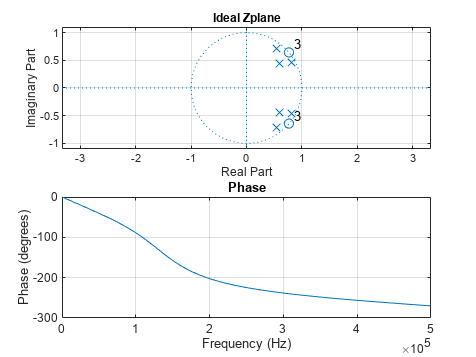

%Poles and Zeros Plot
zplane(num,den)
grid
title("Ideal Zplane");

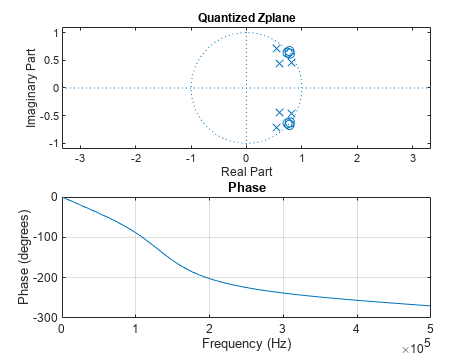

zplane(numq,denq)
title("Quantized Zplane");

%Impulse Response 
impfvt = fvtool(num,den,numq,denq,'Analysis','impulse');
legend(impfvt,"Ideal","Quantized");
impfvt.SpecifyLength = 'Specified';
impfvt.Length = 100;

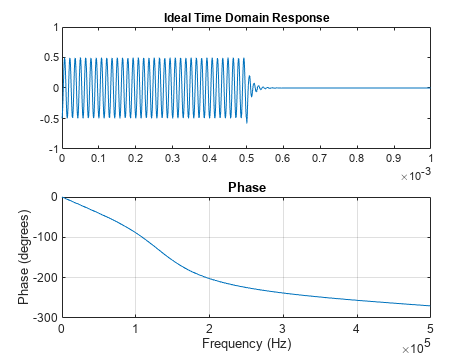

%Time Domain Simulation
samples = 1000; % Number of signal samples
t = (0:samples-1)/fs;              % Time vector
w = 2*pi*70e3;
input_sinusoid = Signal*sin(w*t);
input_sinusoid_quantized = a2dT(input_sinusoid,bits);
% plot(t,input_sinusoid), grid on, ylim([-1 1])
imp = [1; zeros(samples-1,1)];
h = filter(num,den,imp);
% stem(0:samples-1,h);
w = conv(input_sinusoid,h,'same');
plot(t,w), ylim([-1 1]), title("Ideal Time Domain Response");

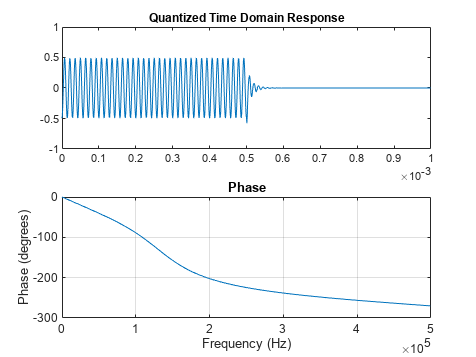

hq = filter(numq,denq,imp);
% stem(0:samples-1,hq);
wq = conv(input_sinusoid_quantized,hq,'same');
plot(t,wq), ylim([-1 1]), title("Quantized Time Domain Response");

%Hardware Calculations
adder_gatecount = bits*4;
multiplier_gatecount = 2*bits^2;
register_gatecount = 5*bits;

syms P
power_consumption = (adder_gatecount + multiplier_gatecount + register_gatecount)*P

$$power\_consumption = 455\,P$$